# Create and Train a Deep Learning Model

Script for creating and training a deep learning network with the following properties:

Run this script to create the network layers, import training and validation data, and train the network. The network layers are stored in the workspace variable `lgraph`. The trained network is stored in the workspace variable `net`.

To learn more, see [Generate MATLAB Code From Deep Network Designer](matlab:helpview('deeplearning','generate_matlab_code')).

Auto-generated by MATLAB on 17-Mar-2024 18:00:18

## Load Initial Parameters

Load parameters for network initialization. For transfer learning, the network initialization parameters are the parameters of the initial pretrained network.

trainingSetup = load("C:\Users\sujsh\OneDrive\Documents\MATLAB\SqueezeNetTest\segments\params_2024_03_17__18_00_03.mat");

## Import Data

Import training and validation data.

imdsTrain = imageDatastore("C:\Users\sujsh\OneDrive\Documents\MATLAB\SqueezeNetTest\segments\TrainData","IncludeSubfolders",true,"LabelSource","foldernames");
[imdsTrain, imdsValidation] = splitEachLabel(imdsTrain,0.7);

## Augmentation Settings

imageAugmenter = imageDataAugmenter(...
    "RandRotation",[-90 90],...
    "RandScale",[1 2],...
    "RandXReflection",true);

% Resize the images to match the network input layer.
augimdsTrain = augmentedImageDatastore([227 227 3],imdsTrain,"DataAugmentation",imageAugmenter);
augimdsValidation = augmentedImageDatastore([227 227 3],imdsValidation);

## Set Training Options

Specify options to use when training.

opts = trainingOptions("sgdm",...
    "ExecutionEnvironment","auto",...
    "InitialLearnRate",0.0001,...
    "MaxEpochs",8,...
    "MiniBatchSize",35,...
    "Shuffle","every-epoch",...
    "ValidationFrequency",5,...
    "Plots","training-progress",...
    "ValidationData",augimdsValidation);

## Create Layer Graph

Create the layer graph variable to contain the network layers.

lgraph = layerGraph();

## Add Layer Branches

Add the branches of the network to the layer graph. Each branch is a linear array of layers.

tempLayers = [
    imageInputLayer([227 227 3],"Name","data","Mean",trainingSetup.data.Mean)
    convolution2dLayer([3 3],64,"Name","conv1","Stride",[2 2],"Bias",trainingSetup.conv1.Bias,"Weights",trainingSetup.conv1.Weights)
    reluLayer("Name","relu_conv1")
    maxPooling2dLayer([3 3],"Name","pool1","Stride",[2 2])
    convolution2dLayer([1 1],16,"Name","fire2-squeeze1x1","Bias",trainingSetup.fire2_squeeze1x1.Bias,"Weights",trainingSetup.fire2_squeeze1x1.Weights)
    reluLayer("Name","fire2-relu_squeeze1x1")];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    convolution2dLayer([1 1],64,"Name","fire2-expand1x1","Bias",trainingSetup.fire2_expand1x1.Bias,"Weights",trainingSetup.fire2_expand1x1.Weights)
    reluLayer("Name","fire2-relu_expand1x1")];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    convolution2dLayer([3 3],64,"Name","fire2-expand3x3","Padding",[1 1 1 1],"Bias",trainingSetup.fire2_expand3x3.Bias,"Weights",trainingSetup.fire2_expand3x3.Weights)
    reluLayer("Name","fire2-relu_expand3x3")];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    depthConcatenationLayer(2,"Name","fire2-concat")
    convolution2dLayer([1 1],16,"Name","fire3-squeeze1x1","Bias",trainingSetup.fire3_squeeze1x1.Bias,"Weights",trainingSetup.fire3_squeeze1x1.Weights)
    reluLayer("Name","fire3-relu_squeeze1x1")];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    convolution2dLayer([1 1],64,"Name","fire3-expand1x1","Bias",trainingSetup.fire3_expand1x1.Bias,"Weights",trainingSetup.fire3_expand1x1.Weights)
    reluLayer("Name","fire3-relu_expand1x1")];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    convolution2dLayer([3 3],64,"Name","fire3-expand3x3","Padding",[1 1 1 1],"Bias",trainingSetup.fire3_expand3x3.Bias,"Weights",trainingSetup.fire3_expand3x3.Weights)
    reluLayer("Name","fire3-relu_expand3x3")];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    depthConcatenationLayer(2,"Name","fire3-concat")
    maxPooling2dLayer([3 3],"Name","pool3","Padding",[0 1 0 1],"Stride",[2 2])
    convolution2dLayer([1 1],32,"Name","fire4-squeeze1x1","Bias",trainingSetup.fire4_squeeze1x1.Bias,"Weights",trainingSetup.fire4_squeeze1x1.Weights)
    reluLayer("Name","fire4-relu_squeeze1x1")];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    convolution2dLayer([1 1],128,"Name","fire4-expand1x1","Bias",trainingSetup.fire4_expand1x1.Bias,"Weights",trainingSetup.fire4_expand1x1.Weights)
    reluLayer("Name","fire4-relu_expand1x1")];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    convolution2dLayer([3 3],128,"Name","fire4-expand3x3","Padding",[1 1 1 1],"Bias",trainingSetup.fire4_expand3x3.Bias,"Weights",trainingSetup.fire4_expand3x3.Weights)
    reluLayer("Name","fire4-relu_expand3x3")];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    depthConcatenationLayer(2,"Name","fire4-concat")
    convolution2dLayer([1 1],32,"Name","fire5-squeeze1x1","Bias",trainingSetup.fire5_squeeze1x1.Bias,"Weights",trainingSetup.fire5_squeeze1x1.Weights)
    reluLayer("Name","fire5-relu_squeeze1x1")];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    convolution2dLayer([1 1],128,"Name","fire5-expand1x1","Bias",trainingSetup.fire5_expand1x1.Bias,"Weights",trainingSetup.fire5_expand1x1.Weights)
    reluLayer("Name","fire5-relu_expand1x1")];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    convolution2dLayer([3 3],128,"Name","fire5-expand3x3","Padding",[1 1 1 1],"Bias",trainingSetup.fire5_expand3x3.Bias,"Weights",trainingSetup.fire5_expand3x3.Weights)
    reluLayer("Name","fire5-relu_expand3x3")];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    depthConcatenationLayer(2,"Name","fire5-concat")
    maxPooling2dLayer([3 3],"Name","pool5","Padding",[0 1 0 1],"Stride",[2 2])
    convolution2dLayer([1 1],48,"Name","fire6-squeeze1x1","Bias",trainingSetup.fire6_squeeze1x1.Bias,"Weights",trainingSetup.fire6_squeeze1x1.Weights)
    reluLayer("Name","fire6-relu_squeeze1x1")];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    convolution2dLayer([1 1],192,"Name","fire6-expand1x1","Bias",trainingSetup.fire6_expand1x1.Bias,"Weights",trainingSetup.fire6_expand1x1.Weights)
    reluLayer("Name","fire6-relu_expand1x1")];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    convolution2dLayer([3 3],192,"Name","fire6-expand3x3","Padding",[1 1 1 1],"Bias",trainingSetup.fire6_expand3x3.Bias,"Weights",trainingSetup.fire6_expand3x3.Weights)
    reluLayer("Name","fire6-relu_expand3x3")];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    depthConcatenationLayer(2,"Name","fire6-concat")
    convolution2dLayer([1 1],48,"Name","fire7-squeeze1x1","Bias",trainingSetup.fire7_squeeze1x1.Bias,"Weights",trainingSetup.fire7_squeeze1x1.Weights)
    reluLayer("Name","fire7-relu_squeeze1x1")];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    convolution2dLayer([1 1],192,"Name","fire7-expand1x1","Bias",trainingSetup.fire7_expand1x1.Bias,"Weights",trainingSetup.fire7_expand1x1.Weights)
    reluLayer("Name","fire7-relu_expand1x1")];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    convolution2dLayer([3 3],192,"Name","fire7-expand3x3","Padding",[1 1 1 1],"Bias",trainingSetup.fire7_expand3x3.Bias,"Weights",trainingSetup.fire7_expand3x3.Weights)
    reluLayer("Name","fire7-relu_expand3x3")];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    depthConcatenationLayer(2,"Name","fire7-concat")
    convolution2dLayer([1 1],64,"Name","fire8-squeeze1x1","Bias",trainingSetup.fire8_squeeze1x1.Bias,"Weights",trainingSetup.fire8_squeeze1x1.Weights)
    reluLayer("Name","fire8-relu_squeeze1x1")];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    convolution2dLayer([1 1],256,"Name","fire8-expand1x1","Bias",trainingSetup.fire8_expand1x1.Bias,"Weights",trainingSetup.fire8_expand1x1.Weights)
    reluLayer("Name","fire8-relu_expand1x1")];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    convolution2dLayer([3 3],256,"Name","fire8-expand3x3","Padding",[1 1 1 1],"Bias",trainingSetup.fire8_expand3x3.Bias,"Weights",trainingSetup.fire8_expand3x3.Weights)
    reluLayer("Name","fire8-relu_expand3x3")];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    depthConcatenationLayer(2,"Name","fire8-concat")
    convolution2dLayer([1 1],64,"Name","fire9-squeeze1x1","Bias",trainingSetup.fire9_squeeze1x1.Bias,"Weights",trainingSetup.fire9_squeeze1x1.Weights)
    reluLayer("Name","fire9-relu_squeeze1x1")];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    convolution2dLayer([1 1],256,"Name","fire9-expand1x1","Bias",trainingSetup.fire9_expand1x1.Bias,"Weights",trainingSetup.fire9_expand1x1.Weights)
    reluLayer("Name","fire9-relu_expand1x1")];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    convolution2dLayer([3 3],256,"Name","fire9-expand3x3","Padding",[1 1 1 1],"Bias",trainingSetup.fire9_expand3x3.Bias,"Weights",trainingSetup.fire9_expand3x3.Weights)
    reluLayer("Name","fire9-relu_expand3x3")];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    depthConcatenationLayer(2,"Name","fire9-concat")
    dropoutLayer(0.5,"Name","drop9")
    convolution2dLayer([1 1],2,"Name","conv10","BiasLearnRateFactor",10,"WeightLearnRateFactor",10)
    reluLayer("Name","relu_conv10")
    globalAveragePooling2dLayer("Name","pool10")
    softmaxLayer("Name","prob")
    classificationLayer("Name","ClassificationLayer_predictions")];
lgraph = addLayers(lgraph,tempLayers);

% clean up helper variable
clear tempLayers;

## Connect Layer Branches

Connect all the branches of the network to create the network graph.

lgraph = connectLayers(lgraph,"fire2-relu_squeeze1x1","fire2-expand1x1");
lgraph = connectLayers(lgraph,"fire2-relu_squeeze1x1","fire2-expand3x3");
lgraph = connectLayers(lgraph,"fire2-relu_expand1x1","fire2-concat/in1");
lgraph = connectLayers(lgraph,"fire2-relu_expand3x3","fire2-concat/in2");
lgraph = connectLayers(lgraph,"fire3-relu_squeeze1x1","fire3-expand1x1");
lgraph = connectLayers(lgraph,"fire3-relu_squeeze1x1","fire3-expand3x3");
lgraph = connectLayers(lgraph,"fire3-relu_expand1x1","fire3-concat/in1");
lgraph = connectLayers(lgraph,"fire3-relu_expand3x3","fire3-concat/in2");
lgraph = connectLayers(lgraph,"fire4-relu_squeeze1x1","fire4-expand1x1");
lgraph = connectLayers(lgraph,"fire4-relu_squeeze1x1","fire4-expand3x3");
lgraph = connectLayers(lgraph,"fire4-relu_expand1x1","fire4-concat/in1");
lgraph = connectLayers(lgraph,"fire4-relu_expand3x3","fire4-concat/in2");
lgraph = connectLayers(lgraph,"fire5-relu_squeeze1x1","fire5-expand1x1");
lgraph = connectLayers(lgraph,"fire5-relu_squeeze1x1","fire5-expand3x3");
lgraph = connectLayers(lgraph,"fire5-relu_expand1x1","fire5-concat/in1");
lgraph = connectLayers(lgraph,"fire5-relu_expand3x3","fire5-concat/in2");
lgraph = connectLayers(lgraph,"fire6-relu_squeeze1x1","fire6-expand1x1");
lgraph = connectLayers(lgraph,"fire6-relu_squeeze1x1","fire6-expand3x3");
lgraph = connectLayers(lgraph,"fire6-relu_expand1x1","fire6-concat/in1");
lgraph = connectLayers(lgraph,"fire6-relu_expand3x3","fire6-concat/in2");
lgraph = connectLayers(lgraph,"fire7-relu_squeeze1x1","fire7-expand1x1");
lgraph = connectLayers(lgraph,"fire7-relu_squeeze1x1","fire7-expand3x3");
lgraph = connectLayers(lgraph,"fire7-relu_expand1x1","fire7-concat/in1");
lgraph = connectLayers(lgraph,"fire7-relu_expand3x3","fire7-concat/in2");
lgraph = connectLayers(lgraph,"fire8-relu_squeeze1x1","fire8-expand1x1");
lgraph = connectLayers(lgraph,"fire8-relu_squeeze1x1","fire8-expand3x3");
lgraph = connectLayers(lgraph,"fire8-relu_expand1x1","fire8-concat/in1");
lgraph = connectLayers(lgraph,"fire8-relu_expand3x3","fire8-concat/in2");
lgraph = connectLayers(lgraph,"fire9-relu_squeeze1x1","fire9-expand1x1");
lgraph = connectLayers(lgraph,"fire9-relu_squeeze1x1","fire9-expand3x3");
lgraph = connectLayers(lgraph,"fire9-relu_expand1x1","fire9-concat/in1");
lgraph = connectLayers(lgraph,"fire9-relu_expand3x3","fire9-concat/in2");

## Train Network

Train the network using the specified options and training data.

Training on single CPU.
Initializing input data normalization.
|======================================================================================================================|
|  Epoch  |  Iteration  |  Time Elapsed  |  Mini-batch  |  Validation  |  Mini-batch  |  Validation  |  Base Learning  |
|         |             |   (hh:mm:ss)   |   Accuracy   |   Accuracy   |     Loss     |     Loss     |      Rate       |
|======================================================================================================================|
|       1 |           1 |       00:00:04 |       51.43% |       57.33% |       0.8167 |       0.6559 |      1.0000e-04 |
|       1 |           5 |       00:00:10 |       77.14% |       88.00% |       0.5340 |       0.4106 |      1.0000e-04 |
|       2 |          10 |       00:00:18 |       68.57% |       93.33% |       0.6293 |       0.2433 |      1.0000e-04 |
|       3 |          15 |       00:00:27 |       77.14% |       94.67% |       0.4094 |   

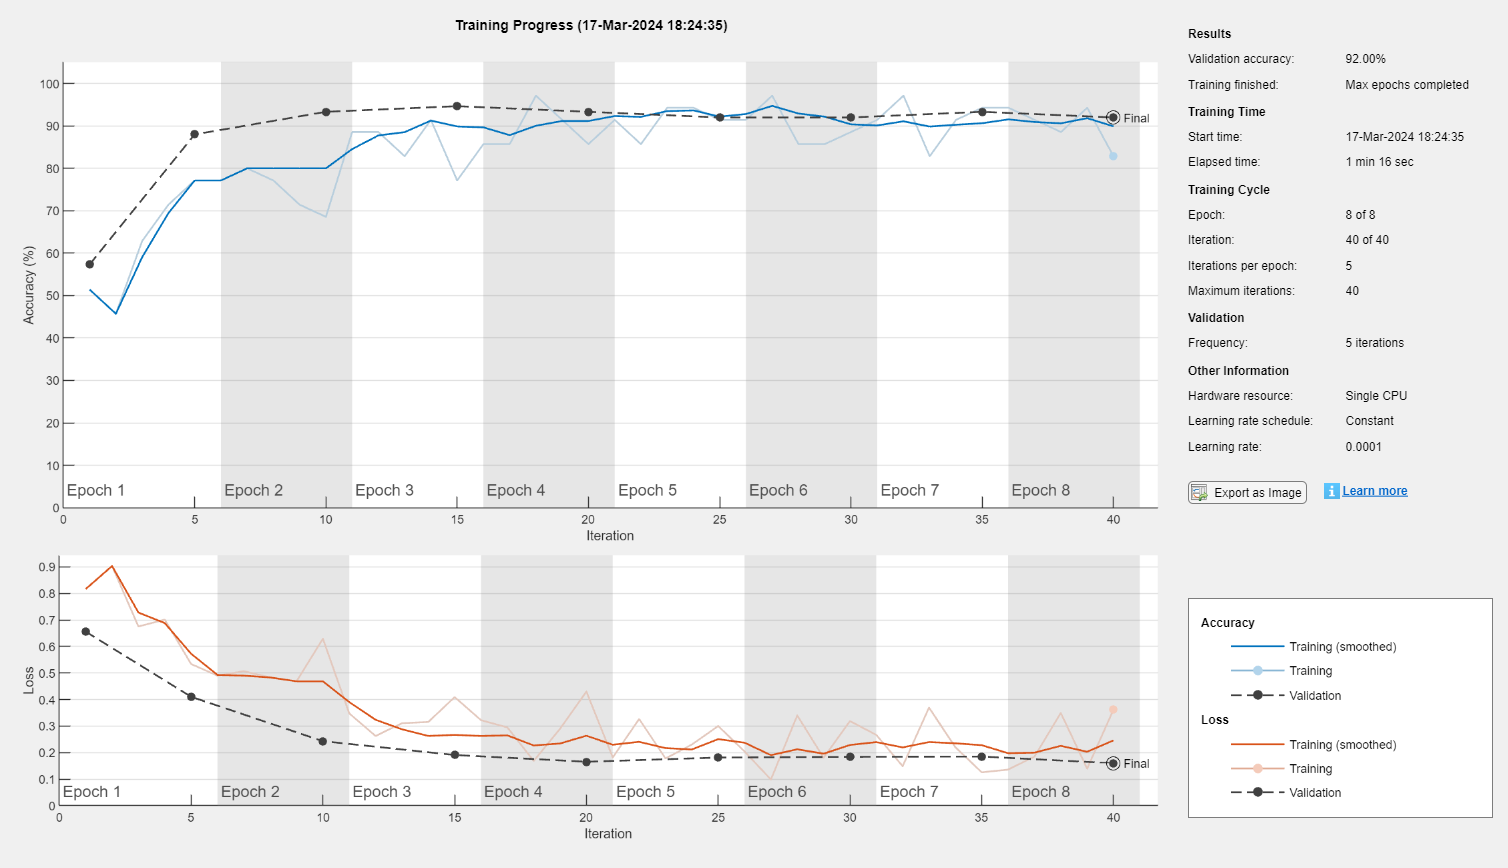

[net, traininfo] = trainNetwork(augimdsTrain,lgraph,opts);